# Simulation sur le disque D0 de centre 0 et de rayon 1

(a) On commence par simuler des points en coordonnées polaires en considérant :

- un rayon R uniforme sur [0,1]

- un angle theta uniforme sur [0, 2*pi]

La fonction unifrnd(a,b,n,p) permet de générer une matrice à n lignes et p colonnes de nombres uniformement distribués sur [a,b].

n=1000;
r=unifrnd(0,1,n,1);
theta=unifrnd(0,2*pi,n,1);
x=r.*cos(theta);
y=r.*sin(theta);
subplot(1,2,1) ; plot(x,y,'.')
axis square;

(b) On simule par rejet : 

- 
$$(\bar{X}, \bar{Y}) \sim U([-1,1]\times [-1,1])$$


- si $(\bar{X}, \bar{Y}) \in D_0$ alors $(X,Y) = (\bar{X}, \bar{Y}) $

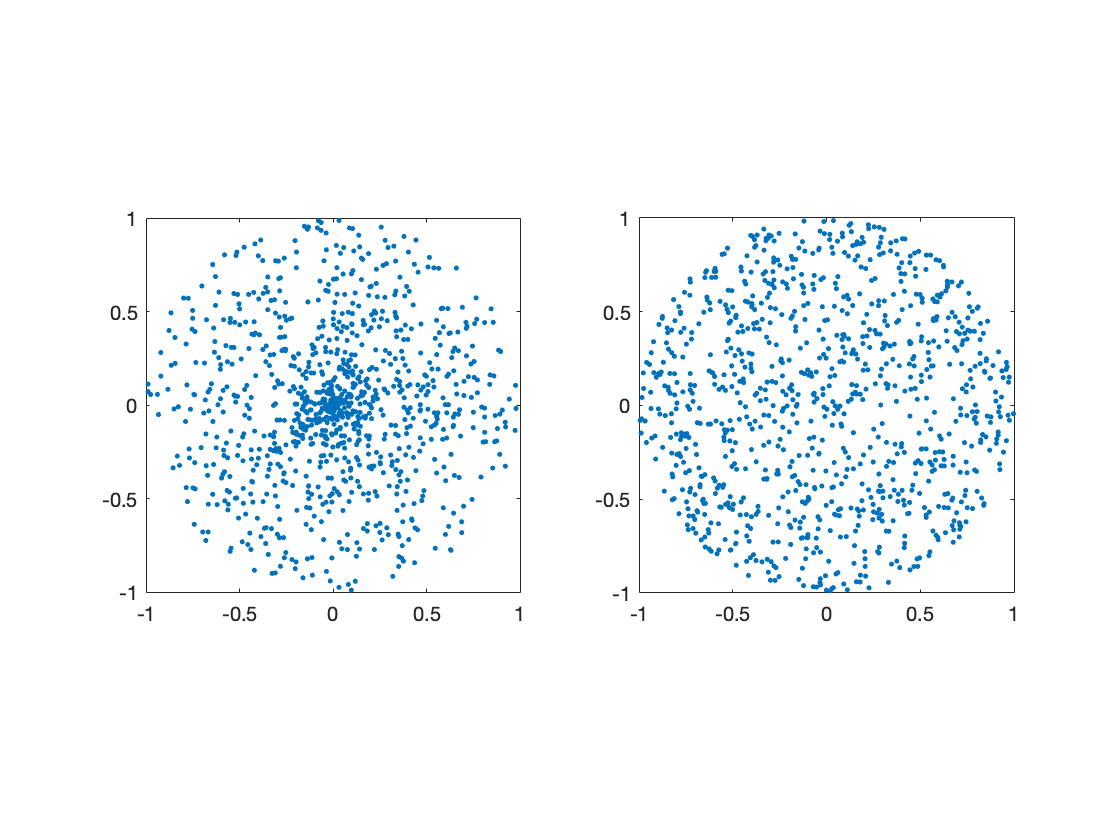

count=0;
x=[ ];y=[ ];% vecteurs vides
while count<n
% on tire deux lois uniformes sur [-1, 1]
Xbarre = unifrnd(-1,1);
Ybarre = unifrnd(-1,1);
    if (Xbarre^2+Ybarre^2 < 1)
        x=[x;Xbarre];y=[y;Ybarre];% on complète le vecteur 
        count=count+1;
    end
end
subplot(1,2,2) ; plot(x,y,'.')
axis square;